## Image presentation and analysis

## Preamble

In this section you will be working with large imagery datasets. These are stored on GitHub, but require a special extension to download from Git, which requires the ability to run Git on your local machine. As many of you are using the Geospatial computers, it will not be possible to install this, and so instead, a direct OneDrive link is provided to the data you will need. Please delete the existing Block 05 **data** folder and replace it with the one that you can [DOWNLOAD FROM THIS LINK](https://newcastle-my.sharepoint.com/:f:/g/personal/nmp65_newcastle_ac_uk/EnYqfa_RMDBAtekP6HqaUB4BQjzLVyz1rtViApthUfDD9g?e=zv67BA).

## Part A: Landsat imagery

In addition to the types of anaysis that we have already undertaken, MATLAB is well-suited to image analysis due to its matrix operations. In this section we will explore some of its mapping capabilities and image analysis functions. Whilst other forms of software are useful for image analysis, MATLAB has some additional benefits, one of which is the reproducibility of maps created and analysis that you undertake, also enabling a reader to produce a map and explore it dynamically. Let's start by using some Landsat 8 imagery downloaded from [GloVis](https://glovis.usgs.gov/app?fullscreen=0). The product selected was the `Landsat 8 OLI/TIRS C1 Level-1` and this represents imagery acquired of a study site in the UK. We will first point MATLAB to the directory containing the datasets:

clear all; close all; clc % clear any variables in the workspace
dirIn = 'H:\Downloads\GEO8026-main\Block 05\data\esk\'; % modify as required
addpath(genpath( 'H:\Downloads\GEO8026-main\Block 05\')); % modify as required

If you take a moment to look through the files that are held within the \`Block 05\data\esk\ `directory, you will see several files. The image files (.tif) are the individual bands that are captured by the satellite imaging system. The final numbers at the end of the file names represent the specific bands, described [here](https://www.usgs.gov/faqs/what-are-band-designations-landsat-satellites?qt-news_science_products=0#qt-news_science_products). The primary bands of interest are likely to be those that capture within the red (B4), blue (B2), green (B3), and near infrared (B5) wavelengths. Let's load the imagery into MATLAB and see what the raw imagery looks like without any manipulation of the bands

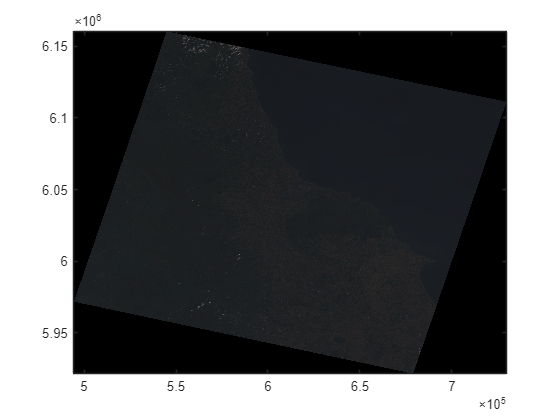

filename = ...
    'LC08_L1TP_203022_20210907_20210916_01_T1_';
channels = ['B4';'B3';'B2';'B5']; % red, green, blue, nir
extension = '.tif';

[B4,R]  = readgeoraster([dirIn, filename,channels(1,:),extension]); % read in the red
[B3]    = readgeoraster([dirIn, filename,channels(2,:),extension]); % read in the green
[B2]    = readgeoraster([dirIn, filename,channels(3,:),extension]); % read in the blue
[B5]    = readgeoraster([dirIn, filename,channels(4,:),extension]); % read in the nir
[X,Y]   = worldGrid(R);
[x]     = X(1,:); % find the coordinates for each of the pixels within the imagery
[y]     = Y(:,1); % find the coordinates for each of the pixels within the imagery

% merge the RGB bands into one variable for display purposes:
bands{1} = im2double(B4); % Red channel
bands{2} = im2double(B3); % Green channel
bands{3} = im2double(B2); % Blue channel

% convert from a cell array to a uint8 array for display purposes
RGBImage = cat(3, bands{1}, bands{2}, bands{3}); % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255)); % Typecasted to uint8 and rescaled to 0-255 range for visualization

% Plot the imagery specifying the [x,y] coordinates and associated pixel values
figure(); % create a new figure
h2 = image(x,y,RGBImage);  % display the image
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct

As you can see, the image is very dark. This is because the histogram is not optimised for visualisation purposes. Let's look at the histogram of the rgb values:

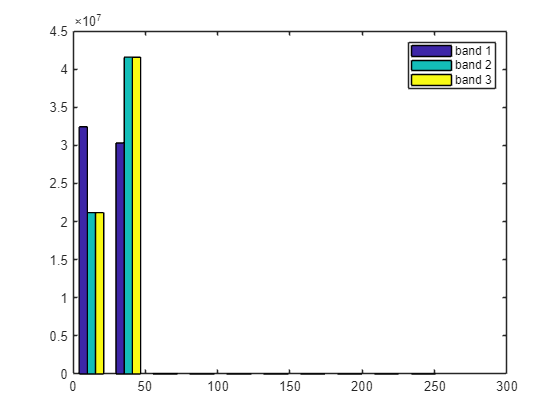

% we need to convert the uint arrays to double for histogram plotting purposes
out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out); % plot the histograms for the three bands
legend('band 1', 'band 2', 'band 3'); % print a legend

We can see that all of the values are skewed to the left of the scale (i.e. < 50), whereas the range of possible color values spans from 0 - 255. This is why the imagery looks so dark. To optimise the display, we need to modify the distribution to improve the way that the image looks:

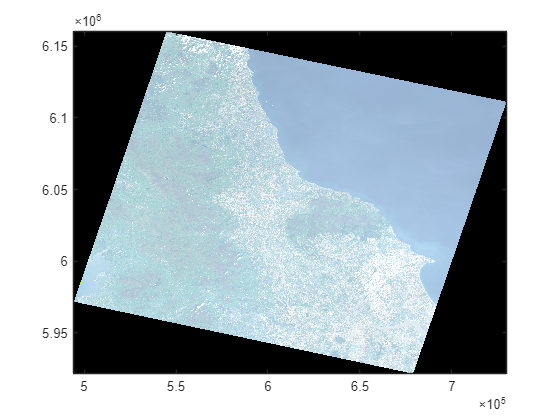

% Stretch the limits of the band so that it covers 98% of the possible pixel range
bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure(); % create the new figure
h2 = image(x,y,RGBImage);  % plot the image
set(gca, 'YDir','normal') % set the y-axis as normal

This looks a lot better but if we were to plot the histogram again, we would see that the values are now skewed to the right. Therefore, let's try one more command to enhance the contrast across the image. We do this by calling `histeq`:

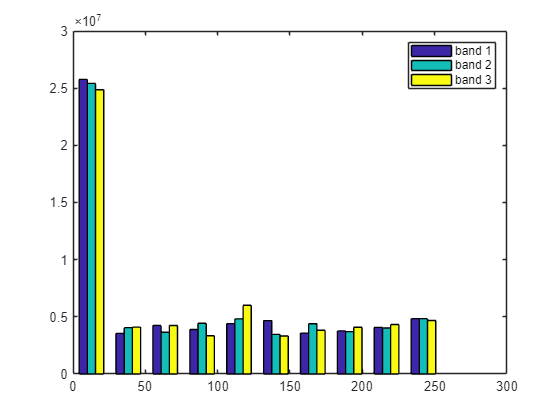

% Run the contrast adjustment on each of the bands seperately
bands{1} = histeq(bands{1});                               % histeq on Red channel
bands{2} = histeq(bands{2});                               % histeq on Green channel
bands{3} = histeq(bands{3});                               % histeq on Blue channel

% brinf the optimised bands back together
RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

% convert back to a double numeric arry to check the histogram is okay:
out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out) % plot the histogram
legend('band 1', 'band 2', 'band 3')
hold off;

Now that the image has been enhanced sufficiently, we can create the final plot of the imagery and begin to bring in additional features, for example ESRI shapefiles. These are stored along with the imagery data within the `/data/esk/` folder. To utilise shapefiles we just need to make sure that they are in the same projected coordinate system as the other datasets that we are presenting. In this case, both the imagery and shapefiles are in UTM Zone 30N:

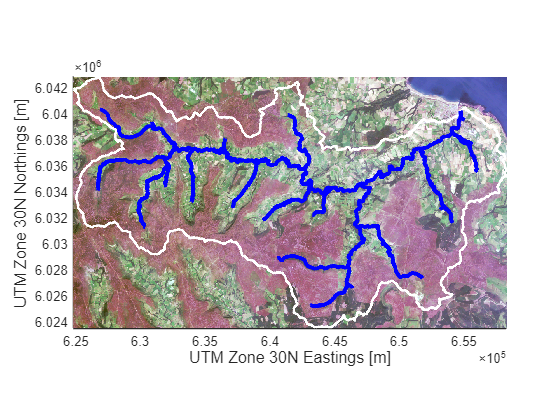

figure(); hold on;
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal');

x_lims = [624800 658300]; % specify the axis limits so that it zooms on the area of interest
y_lims = [6023500,6042900];
axis equal
set(gca,'xlim',x_lims);
set(gca,'ylim',y_lims);

S       = shaperead([dirIn, '\catchment_utm.shp']); % Load in the catchment outline
h1      = plot(S.X,S.Y,'w'); hold on % Plot the catchment outline;
set(h1,'LineWidth',2);
S2      = shaperead([dirIn, '\drainage_utm.shp']); % Load in the river network
for a = 1:length(S2)
    h2 = plot(S2(a).X,S2(a).Y,'b'); set(h2,'LineWidth',3); % Plot the river network
end

hXlabel = xlabel('UTM Zone 30N Eastings [m]'); % Create xlabel
hYlabel = ylabel('UTM Zone 30N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ... % change the font size
    'FontSize',12);